# PRÁCTICA 3: FILTROS DIGITALES FIR

%% 0. CARGA DE DATOS E INICIALIZACIÓN
clear; close all; clc;
% Sustituye por el nombre exacto de tu archivo facilitado
load('PDS_P3_3A_LE2_G4.mat') 
x = x(:); t = t(:); b = b(:); % Aseguramos vectores columna

## 1. FILTRADO DE SEÑALES

a) Frecuencia de muestreo (fs)

fs = 1 / (t(2) - t(1));
fprintf('La frecuencia de muestreo es: %.0f Hz\n', fs);

La frecuencia de muestreo es: 181000 Hz


b) Filtrado Manual (Sumatorio)

M = length(b) - 1; % Orden del filtro
L = length(x);
y_manual = zeros(L, 1);

for n = 1:L
    for k = 1:M+1
        if (n - k + 1) > 0
            y_manual(n) = y_manual(n) + b(k) * x(n - k + 1);
        end
    end
end

c) Filtrado con función `conv`

% La convolución devuelve un vector de longitud L + M
g_conv = conv(b, x); 
% Para comparar con x[n], truncamos o tomamos la parte inicial
g_conv_adj = g_conv(1:L); 

d) Filtrado con función `filter`

% Es el método más eficiente. Devuelve la misma longitud que x.
h_filter = filter(b, 1, x);

e) Comparativa en el Dominio del Tiempo

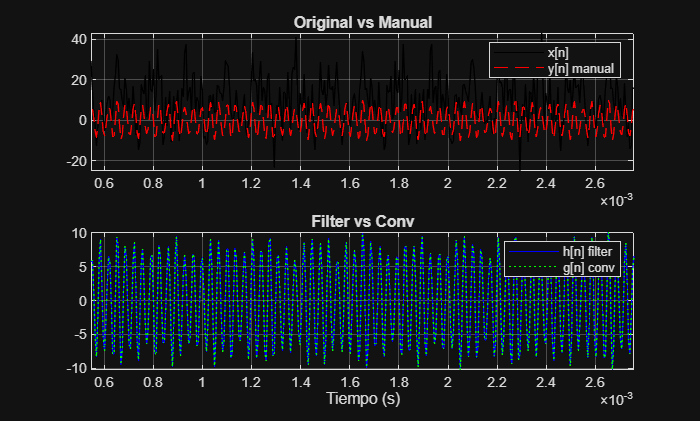

figure('Name', 'Comparativa Métodos de Filtrado');
subplot(2,1,1)
plot(t, x, 'k'); hold on;
plot(t, y_manual, 'r--');
title('Original vs Manual'); legend('x[n]', 'y[n] manual');
xlim([t(100) t(500)]); grid on;

subplot(2,1,2)
plot(t, h_filter, 'b'); hold on;
plot(t, g_conv_adj, 'g:');
title('Filter vs Conv'); legend('h[n] filter', 'g[n] conv');
xlim([t(100) t(500)]); grid on; xlabel('Tiempo (s)');

f) Retardo Transitorio

retardo_muestras = M / 2; % Para filtros FIR de fase lineal
retardo_ms = (retardo_muestras / fs) * 1000;
fprintf('El retardo introducido es de %.3f ms (%d muestras)\n', retardo_ms, retardo_muestras);

El retardo introducido es de 0.276 ms (50 muestras)


## 2. DISEÑO DE FILTROS FIR

Análisis previo para elegir Fc

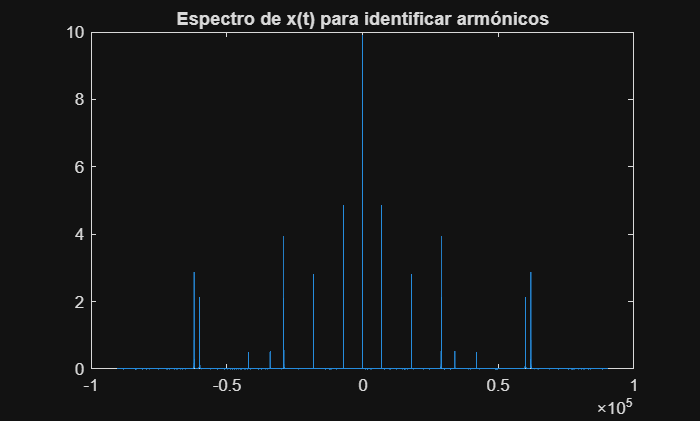

X_f = fftshift(abs(fft(x)/L));
f_axis = linspace(-fs/2, fs/2, L);
figure; plot(f_axis, X_f); title('Espectro de x(t) para identificar armónicos');

a, b) Diseño Paso Bajo (LPF)

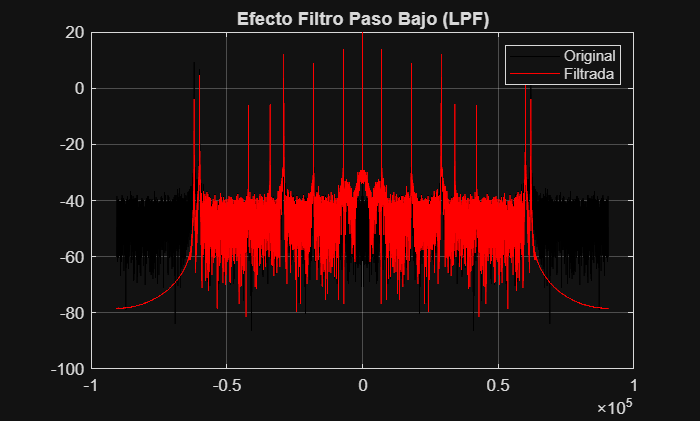

% Supongamos que exportaste los coeficientes como 'LPF_b'
y_lpf = filter(LPF_COEF, 1, x);
Y_LPF_f = fftshift(abs(fft(y_lpf)/L));

figure;
plot(f_axis, 20*log10(X_f), 'k'); hold on;
plot(f_axis, 20*log10(Y_LPF_f), 'r');
title('Efecto Filtro Paso Bajo (LPF)');
legend('Original', 'Filtrada'); grid on;

## 3. ANÁLISIS DE FILTROS: SUPERPOSICIÓN

a, b, c, d) Cascada vs Filtro Único

% 1. Cascada (LPF -> HPF)
y_temp = filter(LPF_COEF, 1, x);
y_cascada = filter(bk_alto, 1, y_temp);

% 2. Filtro Único (Diseñado en fdatool como Bandpass)
y_bandpass = filter(BP_b, 1, x);

% Espectros
Y_CASC_f = fftshift(abs(fft(y_cascada)/L));
Y_BP_f = fftshift(abs(fft(y_bandpass)/L));

e, f) Comparativa Frecuencial

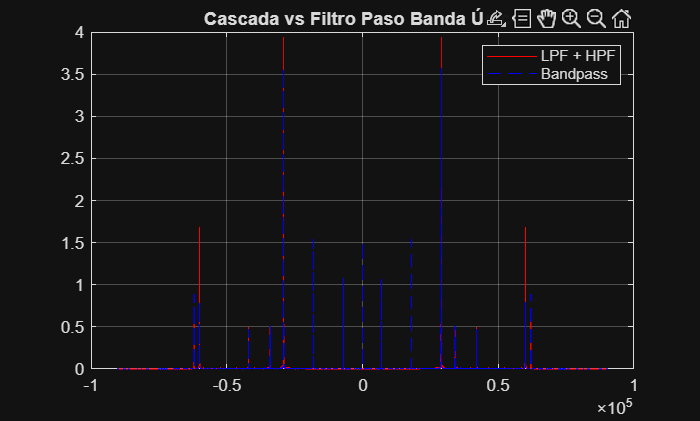

figure;
plot(f_axis, Y_CASC_f, 'r'); hold on;
plot(f_axis, Y_BP_f, 'b--');
title('Cascada vs Filtro Paso Banda Único');
legend('LPF + HPF', 'Bandpass'); grid on;

## 4. ORDEN DEL FILTRO

a, b) Comparación de órdenes con `freqz`

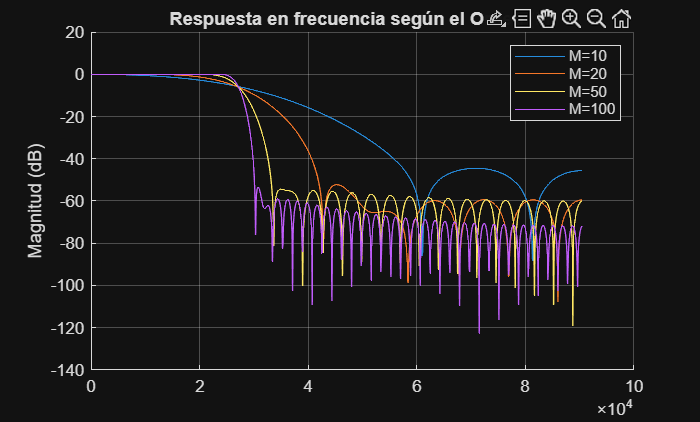

ordenes = [10, 20, 50, 100];
figure; hold on;

for M_val = ordenes
    % Diseñamos un LPF básico para cada orden
    % Usamos fir1 como alternativa rápida para la comparativa
    b_temp = fir1(M_val, 0.3); % Frecuencia normalizada 0.3
    [H, f_freqz] = freqz(b_temp, 1, 1024, fs);
    plot(f_freqz, 20*log10(abs(H)));
end

title('Respuesta en frecuencia según el Orden (M)');
legend('M=10', 'M=20', 'M=50', 'M=100');
ylabel('Magnitud (dB)'); grid on;

c) Cálculo de Retardo según Orden

for M_val = ordenes
    ret_ms = (M_val / 2 / fs) * 1000;
    fprintf('Orden %d -> Retardo: %.4f ms\n', M_val, ret_ms);
end

Orden 10 -> Retardo: 0.0276 ms
Orden 20 -> Retardo: 0.0552 ms
Orden 50 -> Retardo: 0.1381 ms
Orden 100 -> Retardo: 0.2762 ms
